syms s X1 X2 X3 F I1 I2 Vs

%1
A = [4*s^2+17*s+13  -14*s-5;
     -14*s-5  11*s^2+18*s+5];
B = [X1; X2];
C = [0; F];
X = inv(A)*C

$$X = \left(\begin{array}{c} \frac{F\,\left(14\,s+5\right)}{44\,s^{4}+259\,s^{3}+273\,s^{2}+179\,s+40}\\ \frac{F\,\left(4\,s^{2}+17\,s+13\right)}{44\,s^{4}+259\,s^{3}+273\,s^{2}+179\,s+40} \end{array}\right)$$

g1=tf([14 5],[44 259 273 179 40])

g1 =
 
                 14 s + 5
  ---------------------------------------
  44 s^4 + 259 s^3 + 273 s^2 + 179 s + 40
 
Continuous-time transfer function.
Model Properties


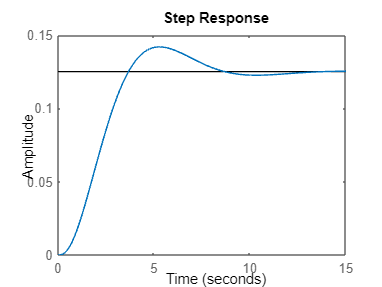

step(g1)


%2
A = [4*s^2+3*s+6      -3*s            0;
        -3*s       4*s^2+5*s+5       -5;
          0            -5        4*s^2+2*s+5];
B = [X1; X2; X3];
C = [0; F; 0];
X = inv(A)*C

$$X = \begin{array}{l} \left(\begin{array}{c} \frac{3\,F\,\sigma_{3}}{2\,\left(32\,s^{5}+80\,s^{4}+172\,s^{3}+220\,s^{2}+180\,s+105\right)}\\ \frac{F\,\sigma_{3}\,\sigma_{2}}{\sigma_{1}}\\ \frac{5\,F\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(32\,s^{6}+80\,s^{5}+172\,s^{4}+220\,s^{3}+180\,s^{2}+105\,s\right)\\ \sigma_{2}=4\,s^{2}+3\,s+6\\ \sigma_{3}=4\,s^{2}+2\,s+5 \end{array}$$

g2=tf([20 15 6],[64 160 344 440 360 210])

g2 =
 
                  20 s^2 + 15 s + 6
  --------------------------------------------------
  64 s^5 + 160 s^4 + 344 s^3 + 440 s^2 + 360 s + 210
 
Continuous-time transfer function.
Model Properties


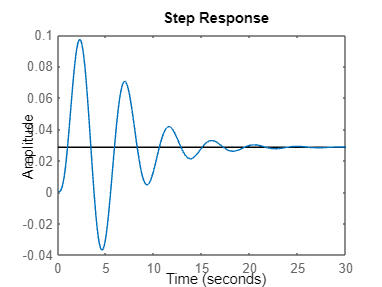

step(g2)



%3
A = [3*s+3 -3;
     -3   2*s+6];
X = [I1;I2];
B = [Vs;0];
Y = inv(A)*B

$$Y = \left(\begin{array}{c} \frac{2\,\mathrm{Vs}\,\left(s+3\right)}{3\,\left(2\,s^{2}+8\,s+3\right)}\\ \frac{\mathrm{Vs}}{2\,s^{2}+8\,s+3} \end{array}\right)$$

g3=tf([4 12 0],[6 24 9])

g3 =
 
    4 s^2 + 12 s
  ----------------
  6 s^2 + 24 s + 9
 
Continuous-time transfer function.
Model Properties


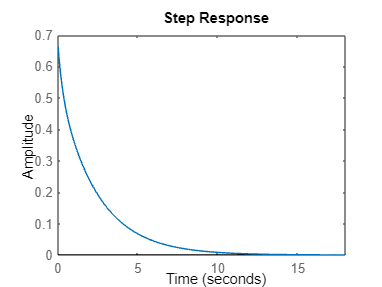

step(g3)



%4
A = [1/(9*s)+1/(12*s)+14 -12-1/(12*s);
     -12-1/(12*s) 1/(12*s)+12*s+23];
X = [I1;I2];
B = [Vs;0];
Y = inv(A)*B

$$Y = \left(\begin{array}{c} \frac{9\,\mathrm{Vs}\,s\,\left(144\,s^{2}+276\,s+1\right)}{18144\,s^{3}+19476\,s^{2}+393\,s+1}\\ \frac{9\,\mathrm{Vs}\,s\,\left(144\,s+1\right)}{18144\,s^{3}+19476\,s^{2}+393\,s+1} \end{array}\right)$$


%g4=tf([15552 29808 108 0 0],[18144 19476 393 1])
g4=tf([15552 108 0 0],[18144 19476 393 1])

g4 =
 
         15552 s^3 + 108 s^2
  ---------------------------------
  18144 s^3 + 19476 s^2 + 393 s + 1
 
Continuous-time transfer function.
Model Properties


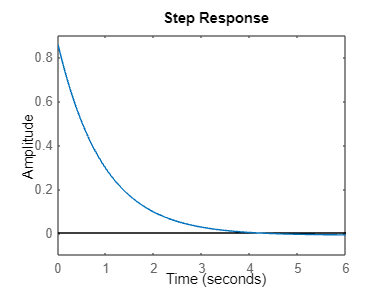

step(g4)